# Controllers Design


$$M=k\sqrt{L_1 L_2 }=\;k\;\sqrt{L\cdot \frac{L}{2\ldotp 33}}=k\;\frac{L}{\sqrt{2\ldotp 33}}\;\;\;\;$$


### Dataset Upload

clc; clear all; close all

L_nom = 36.5e-6;
Lm_nom = 0.99*L_nom/sqrt(2.33);
C_nom = 100e-06;


load("dataset\20_30.mat"); C1 = C; k1 = k; Lm1 = k1*L_nom/sqrt(2.33);
load("dataset\25_35.mat"); C2 = C; k2 = k; Lm2 = k2*L_nom/sqrt(2.33);
load("dataset\30_35_40.mat"); C3 = C; k3 = k; Lm3 = k3*L_nom/sqrt(2.33);
load("dataset\45_50_60.mat"); C4 = C; k4 = k; Lm4 = k4*L_nom/sqrt(2.33);

Lm_bm = mean([Lm1, Lm2, Lm3, Lm4]);
C_bm = mean([C1, C2, C3, C4]);

fprintf('Variation to Real Value\n Lm: %0.3f %%\t C: %0.3f %%', (1-Lm_bm/Lm_nom)*100, (1-C_bm/C_nom)*100);

Variation to Real Value
 Lm: 33.533 %	 C: -19.428 %

### System Definition

DuCy=30;  % The range is 0-60 % duty cycle
I_Lo=0; V_Co=0;
Vg=5; Vd=0.7;
Vs=[Vg Vd];
X=[I_Lo V_Co];


[A,B,C,D,G_nom] =flyback_ss(Vs,X,DuCy,Lm_bm,C_bm);
G_nom

G_nom =
 
           3.511e10
  ---------------------------
  s^2 + 1.907e04 s + 8.244e10
 
Continuous-time transfer function.



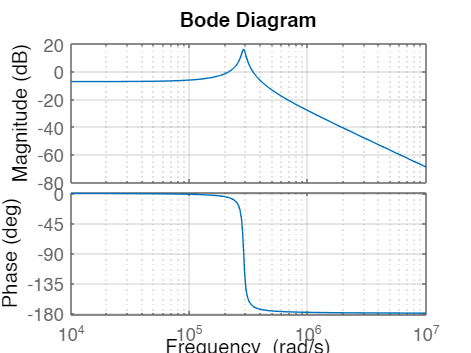

bode(G_nom); grid on


G_fract = flyback_fract(Vs,X,DuCy/100)

Fractional-order transfer function:
               7
-------------------------------
5e-11s^{1.9}+5e-06s^{0.95}+1.96


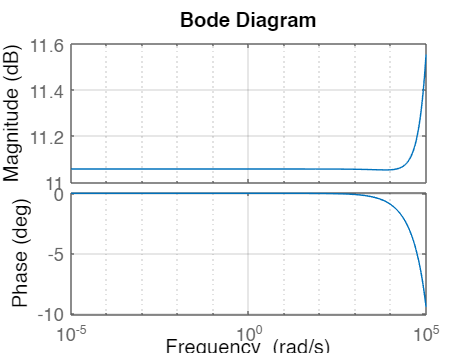

bode(G_fract); grid on


Gz = c2d(G_nom,1e-5,'Tustin');

### Internal Model Control

s=tf('s');
stepinfo(G_nom)

ans = struct with fields:
         RiseTime: 3.7234e-06
    TransientTime: 4.0611e-04
     SettlingTime: 4.0611e-04
      SettlingMin: 0.0802
      SettlingMax: 0.8095
        Overshoot: 90.0893
       Undershoot: 0
             Peak: 0.8095
         PeakTime: 1.0942e-05


lambda = 5e-2;
n = 2;

F = 1/(lambda*s+1)^n;
Gc = (1/G_nom)

Gc =
 
  s^2 + 1.907e04 s + 8.244e10
  ---------------------------
           3.511e10
 
Continuous-time transfer function.



P_tilde = G_nom

P_tilde =
 
           3.511e10
  ---------------------------
  s^2 + 1.907e04 s + 8.244e10
 
Continuous-time transfer function.




C = c2d(Gc*F,1e-5,'Tustin')

C =
 
  3.595e-08 z^2 + 2.417e-08 z + 3.378e-08
  ---------------------------------------
            z^2 - 2 z + 0.9996
 
Sample time: 1e-05 seconds
Discrete-time transfer function.



P_tilde_d = c2d(P_tilde,1e-5,'Tustin')

P_tilde_d =
 
  0.2781 z^2 + 0.5561 z + 0.2781
  ------------------------------
     z^2 + 0.6723 z + 0.9396
 
Sample time: 1e-05 seconds
Discrete-time transfer function.

